1. Pentru fiecare tip de spline scrieti o functie care calculeaza coeficientii spline-ului, daca se dau nodurile si valorile functiei.

A se vedea implementarile de la finalul documentului.

2. Evaluati spline-ul pe o multime de puncte, daca se dau nodurile, punctele si coeficientii. 

x = [1 1.5 2 3];
f = exp(x);

[s_cpl_a, s_cpl_b, s_cpl_c, s_cpl_d] = Splinecubic(x,f,0,[f,f]);
[s_dv2_a, s_dv2_b, s_dv2_c, s_dv2_d] = Splinecubic(x,f,1,[f,f]);
[s_nat_a, s_nat_b, s_nat_c, s_nat_d] = Splinecubic(x,f,2);
[s_dBr_a, s_dBr_b, s_dBr_c, s_dBr_d] = Splinecubic(x,f,3);

t = linspace(x(1),x(size(x,2)));
f = exp(t)';
s_cpl = valspline(x, s_cpl_a, s_cpl_b, s_cpl_c, s_cpl_d, t);
s_dv2 = valspline(x, s_dv2_a, s_dv2_b, s_dv2_c, s_dv2_d, t);
s_nat = valspline(x, s_nat_a, s_nat_b, s_nat_c, s_nat_d, t);
s_dBr = valspline(x, s_dBr_a, s_dBr_b, s_dBr_c, s_dBr_d, t);

err_cpl = max(abs(s_cpl-f))

err_cpl = 2.4918

err_dv2 = max(abs(s_dv2-f))

err_dv2 = 0.2729

err_nat = max(abs(s_nat-f))

err_nat = 0.4889

err_dBr = max(abs(s_dBr-f))

err_dBr = 15.5842

3. Desenati o curba spline cubica parametrica ce trece printr-o multime de puncte date.

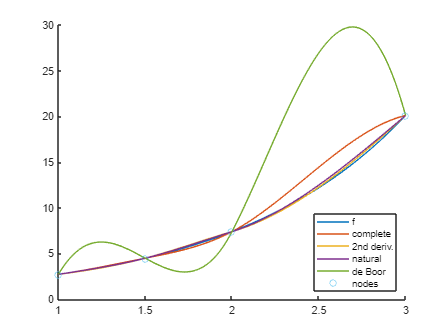

clf
hold on
plot(t,f)
plot(t,s_cpl)
plot(t,s_dv2)
plot(t,s_nat)
plot(t,s_dBr)
scatter(x,exp(x))
legend(["f","complete","2nd deriv.","natural","de Boor","nodes"],"Location","southeast")
hold off

Functii pentru determinarea si evaluarea spline-urilor cubice.

function [a,b,c,d]=Splinecubic(x,f,tip,der)
%SPLINECUBIC - determina coeficientii spline-ului cubic
%x - abscisele
%f - ordonatele
%tip - 0 complet
% 1 cu derivate secunde
% 2 natural
% 3 not a knot (deBoor)
%der - informatii despre derivate
% [f’(a),f’(b)] pentru tipul 0
% [f’’(a), f’’(b)] pentru tipul 1
    if (nargin<4) || (tip==2) 
        der=[0,0]; 
    end
    n=length(x);
    %sortare noduri
    if any(diff(x)<0)
        [x,ind]=sort(x); 
    else 
        ind=1:n; 
    end
    y=f(ind); x=x(:); y=y(:);
    %obtin ecuatiile 2 ... n-1
    dx=diff(x); ddiv=diff(y)./dx;
    ds=dx(1:end-1); dd=dx(2:end);
    dp=2*(ds+dd);
    md=3*(dd.*ddiv(1:end-1)+ds.*ddiv(2:end));
    %tratare diferentiata tip - ecuatiile 1,n
    switch tip
        case 0 %complet
            dp1=1; dpn=1; vd1=0; vdn=0;
            md1=der(1); mdn=der(2);
        case {1, 2} %d2 si natural        
            dp1=2; dpn=2; vd1=1; vdn=1;
            md1=3*ddiv(1)-0.5*dx(1)*der(1);
            mdn=3*ddiv(end)+0.5*dx(end)*der(2);
        case 3 %deBoor
            x31=x(3)-x(1);xn=x(n)-x(n-2);
            dp1=dx(2); dpn=dx(end-1);
            vd1=x31; vdn=xn;
            md1=((dx(1)+2*x31)*dx(2)*ddiv(1)+dx(1)^2*ddiv(2))/x31;
            mdn=(dx(end)^2*ddiv(end-1)+(2*xn+dx(end))*dx(end-1)*...
            ddiv(end))/xn;
    end
    %construiesc sistemul rar
    dp=[dp1;dp;dpn]; dp1=[0;vd1;dd];
    dm1=[ds;vdn;0]; md=[md1;md;mdn];
    A=spdiags([dm1,dp,dp1],-1:1,n,n);
    m=A \ md;
    d=y(1:end-1);
    c=m(1:end-1);
    a=[(m(2:end)+m(1:end-1)-2*ddiv)./(dx.^2)];
    b=[(ddiv-m(1:end-1))./dx-dx.*a];
end

function z= valspline(x,a,b,c,d,t)
%evaluare spline
%apel z=valspline(x,a,b,c,d,t)
%z - valorile
%t - punctele in care se face evaluare
%x - nodurile
%a,b,c,d - coeficientii
    n=length(x);
    x=x(:); t=t(:);
    k = ones(size(t));
    for j = 2:n-1
        k(x(j) <= t) = j;
    end
    % Evaluare interpolant
    s = t - x(k);
    z = d(k) + s.*(c(k) + s.*(b(k) + s.*a(k)));
end